# Fiore's linear method

addpath('../0.utils');

% Caricamento informazioni camera
load('imgInfo.mat');

% Immagine
img = imread('cav.jpg');

% Informazioni immagine
m = imgInfo.punti2DImg;
m = [m ones(size(m,1),1)]';
M = imgInfo.punti3DImg;
M = [M ones(size(M,1),1)]';
K = imgInfo.K;

Calculate the orientation using Fiore's method, obtain the PPM and reproject the points.

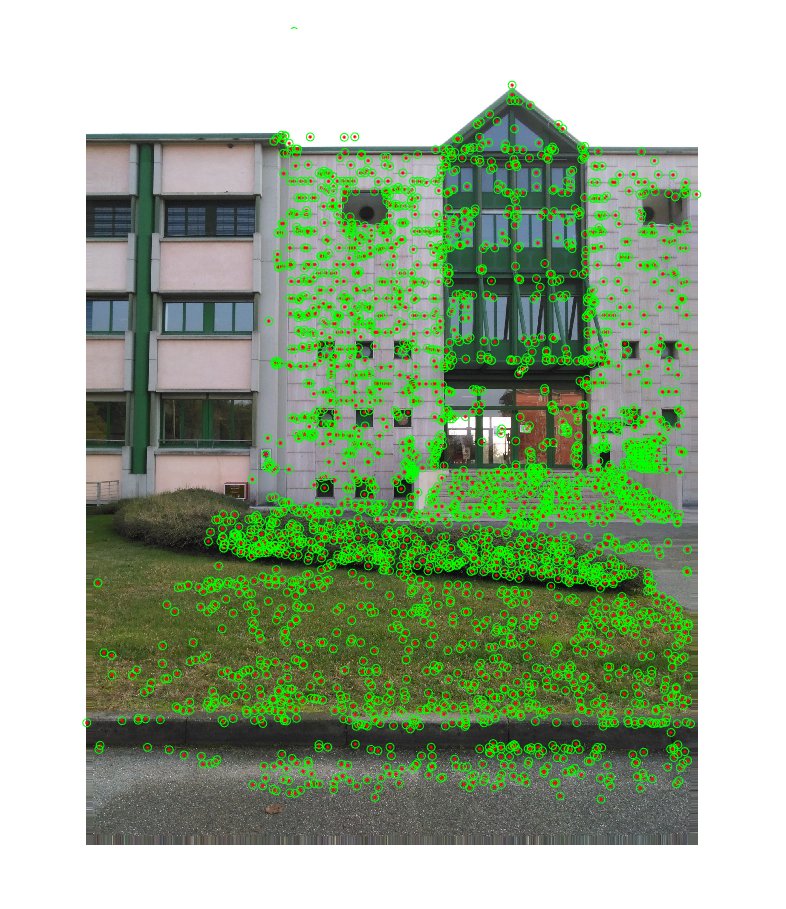

[s,R,t] = fiore(K, m(:,1:100), M(:,1:100));
P = K*[R t];

m_reproj = project(P,M);

figure(1);
imshow(img);
hold on;
plot(m(1,:),m(2,:),'r.');
plot(m_reproj(1,:),m_reproj(2,:),'go');